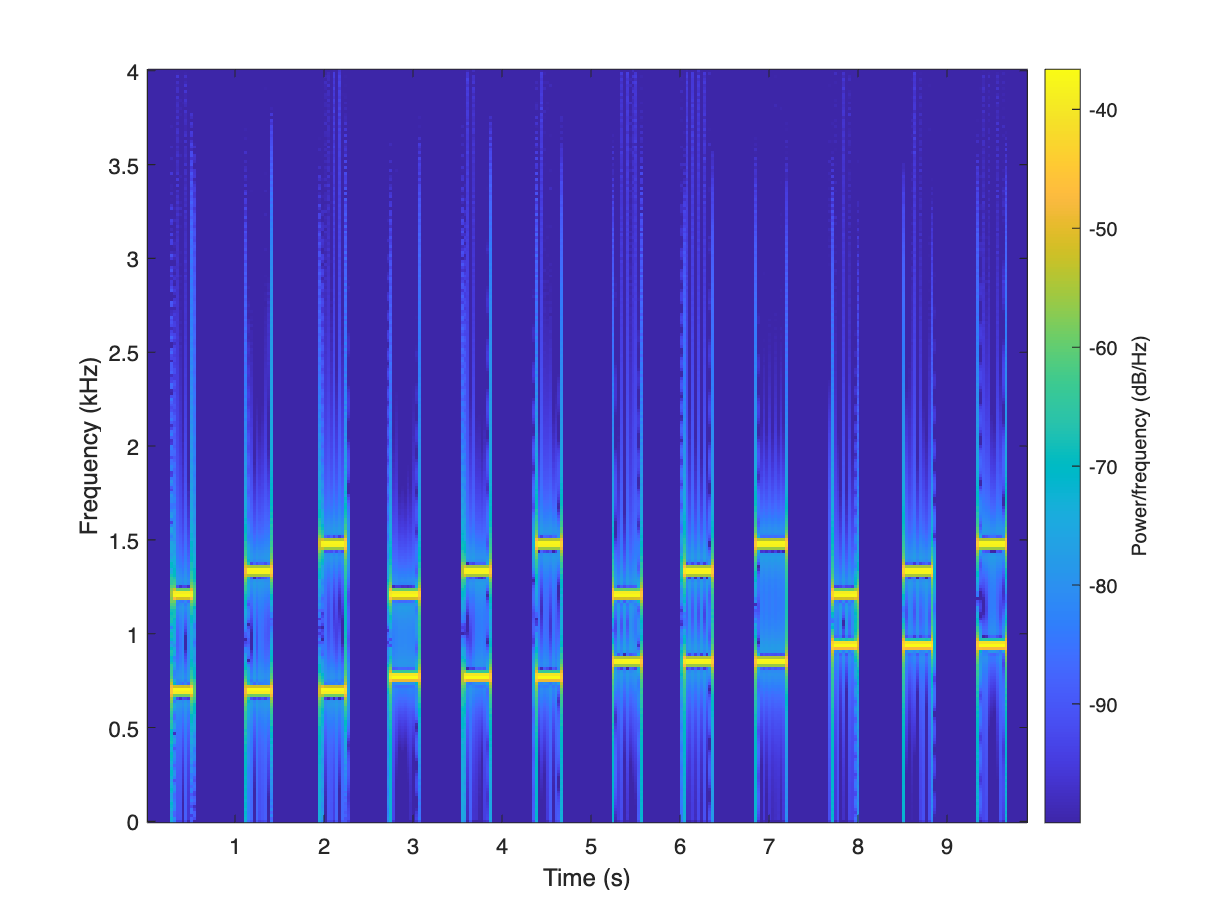

[x, fs] = audioread('dtmf.wav');
win_len = 512;     % wielkość okna do analizy
win_overlap = 256; % nakładanie ramek
nfft = 512;        % liczba próbek do FFT

spectrogram(x, win_len, win_overlap, nfft, fs, 'MinThreshold', -100, 'yaxis')

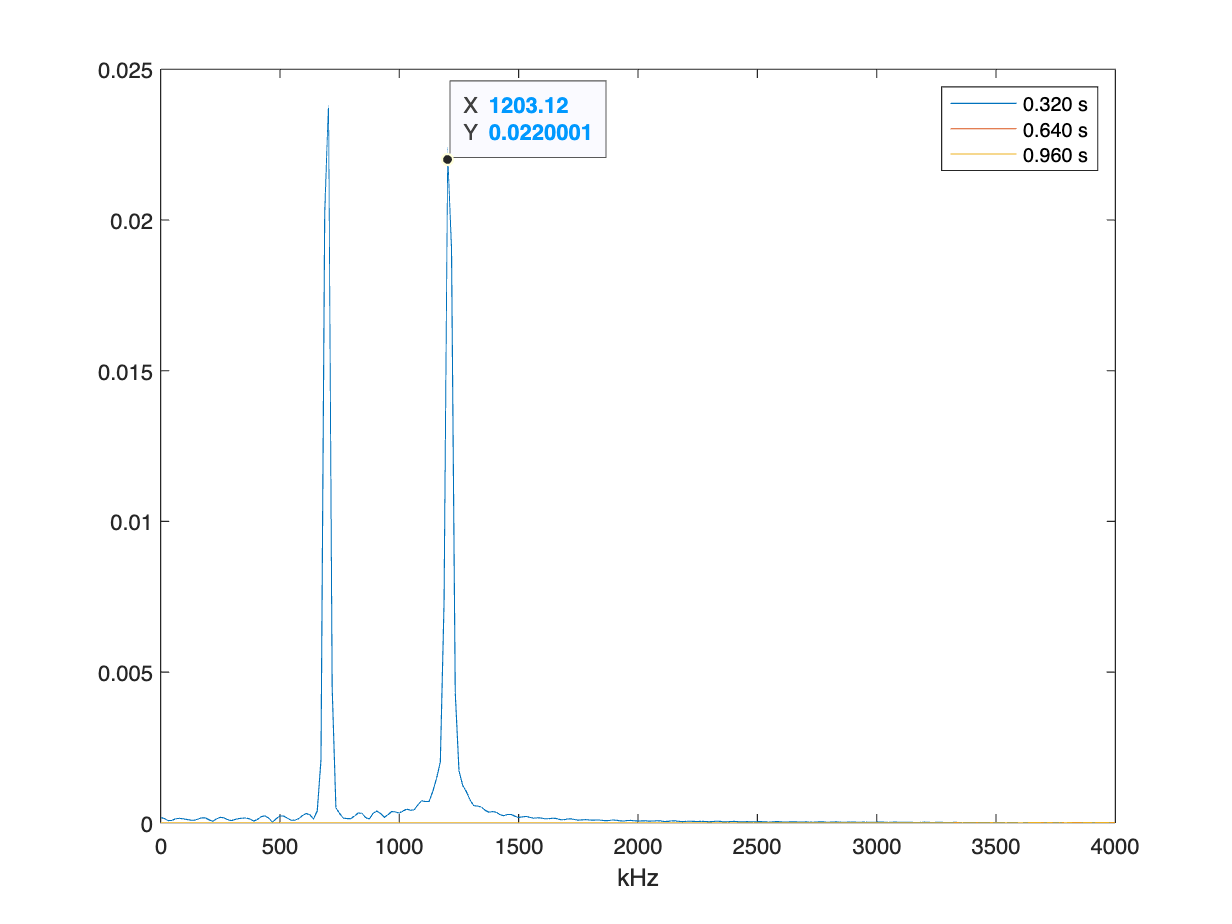

[x, fs] = audioread("dtmf.wav");

win_len = 512;     % wielkość okna do analizy
win_overlap = 256; % nakładanie ramek
nfft = 512;        % liczba próbek do FFT

% wyznaczenie widma częstotliwości w oknach i wyznaczenie amplitudy funkcji składowych
[s, f, t] = spectrogram(x, win_len, win_overlap, nfft, fs);
A = abs(s) / nfft;

% wyświetlenie amplitudy trzech wybranych okienek
figure;
leg = [];
for i=[10, 20, 30]
    plot(f, A(:, i))
    xlabel("kHz");
    hold on
    leg = [leg, sprintf("%.3f s", t(i))];
end
legend(leg);

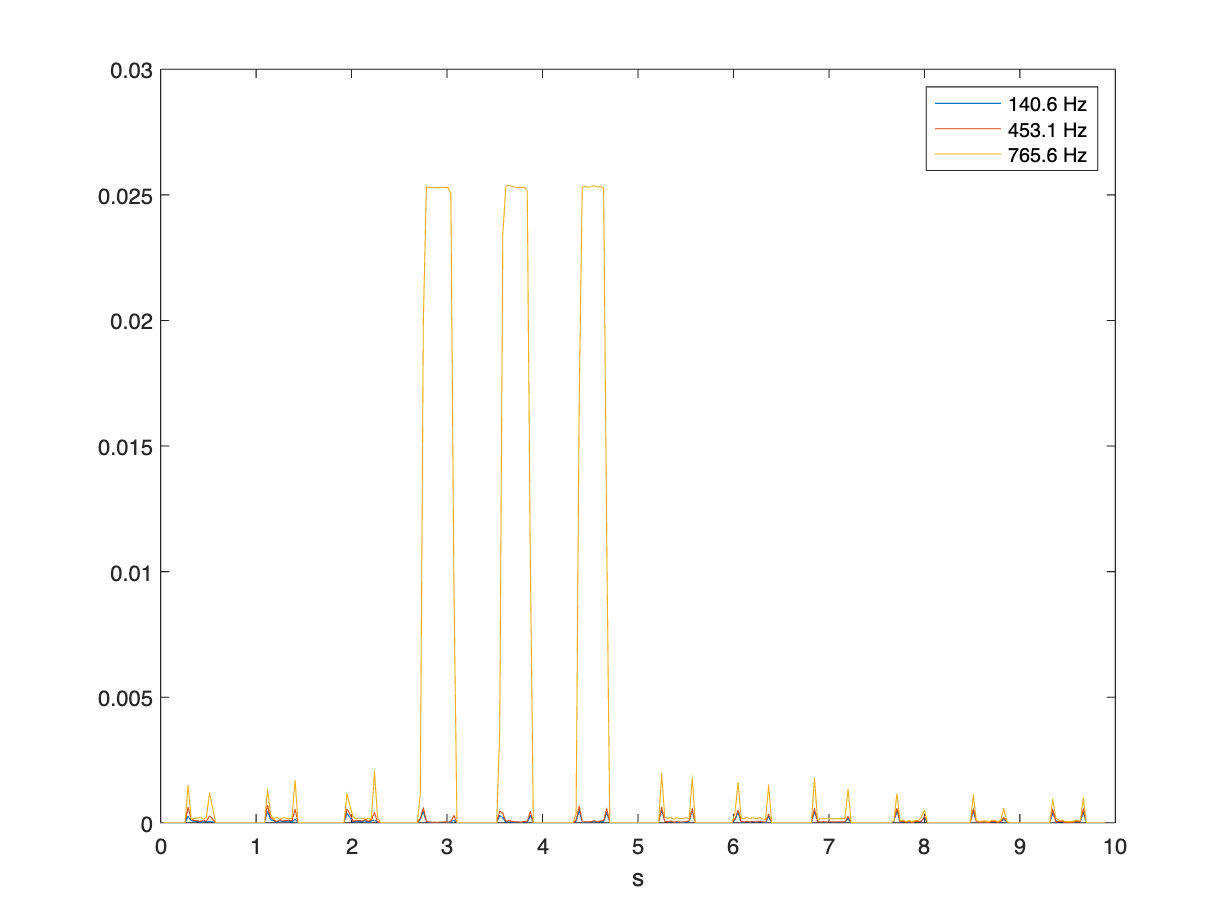


% wyświetlenie przebiegu czasowego trzech wybranych częstotliwości
figure;
leg = [];
for i=[10, 30, 50]
    plot(t, A(i, :))
    xlabel("s");
    hold on
    leg = [leg, sprintf("%.1f Hz", f(i))];
end
legend(leg);

## Analiza sekwencji wciśniętych klawiszyse

sequence = dtmf(x, fs)

sequence = "12345689*0#"